clear; clc;

% Loading data
calib_rotate = load('calib1_rotate.mat');     % For magnetometer calibration
calib_straight = load('calib2_straight.mat'); % For IMU and ToF calibration

stationary_idx = calib_straight.out.GT_time.time <= 60;

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");
task1 = [task1_1, task1_2, task1_3, task1_4, task1_5];

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");
task2 = [task2_1, task2_2, task2_3, task2_4, task2_5];

    {'A_mag'     }
    {'accel_bias'}
    {'b_mag'     }
    {'gyro_bias' }
    {'tof_bias'  }



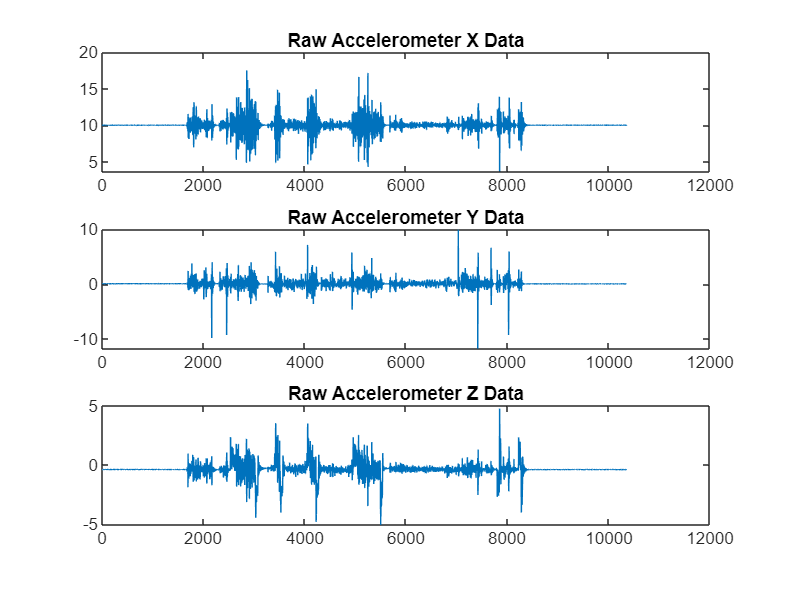

t=0.99s: X=-0.53, Y=4.33, Yaw=-96.4°
t=2.00s: X=-2.09, Y=10.33, Yaw=-96.4°
t=3.00s: X=-4.68, Y=16.66, Yaw=-96.4°
t=4.00s: X=-8.32, Y=23.35, Yaw=-96.4°
t=5.00s: X=-13.00, Y=30.37, Yaw=-96.4°
t=6.00s: X=-18.72, Y=37.75, Yaw=-96.5°
t=7.00s: X=-25.49, Y=45.46, Yaw=-96.5°
t=8.00s: X=-33.30, Y=53.50, Yaw=-96.5°
t=9.00s: X=-42.17, Y=61.87, Yaw=-96.5°
t=10.00s: X=-52.08, Y=70.56, Yaw=-96.5°
t=11.00s: X=-63.04, Y=79.56, Yaw=-96.5°
t=12.00s: X=-75.04, Y=88.89, Yaw=-96.4°
t=13.00s: X=-88.09, Y=98.54, Yaw=-96.4°
t=14.00s: X=-102.18, Y=108.52, Yaw=-96.4°
t=15.00s: X=-117.31, Y=118.85, Yaw=-96.4°
t=16.00s: X=-133.48, Y=129.52, Yaw=-96.4°
t=17.00s: X=-150.69, Y=140.55, Yaw=-96.5°
t=18.00s: X=-168.62, Y=151.89, Yaw=-96.4°
t=19.00s: X=-187.61, Y=163.58, Yaw=-96.8°
t=20.00s: X=-207.73, Y=175.60, Yaw=-96.8°
t=21.00s: X=-229.12, Y=187.94, Yaw=-97.3°
t=22.00s: X=-251.87, Y=200.68, Yaw=-97.3°
t=23.00s: X=-275.80, Y=213.81, Yaw=-97.5°
t=24.00s: X=-300.86, Y=227.32, Yaw=-97.5°
t=25.00s: X=-327.25, Y=241.22, Y

Task 2_1 RMSE: 


Position RMSE: 758.4027 meters


Yaw RMSE: 75.7029 degrees


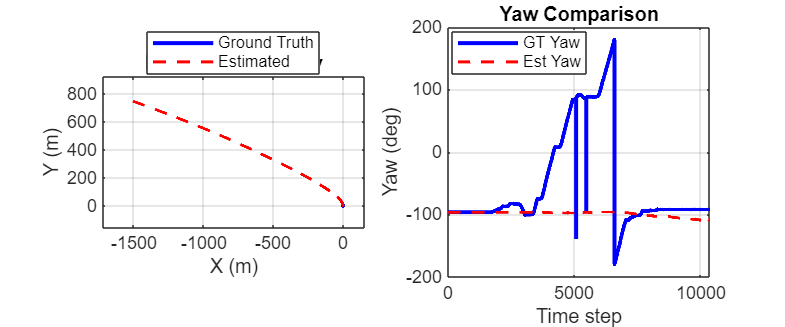

% 1. Calibrating sensors

% 2. Running EKF and storing RMSEs
task2_rmse = [0 0 0 0 0;
              0 0 0 0 0];
for i=1:1
    [X_Est, P_Est, GT] = myEKF(task2(i).out);

    disp("Task 2_" + num2str(i) + " RMSE: ");
    [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, task2(i).out.GT_rotation.signals.values);
    disp(['Position RMSE: ', num2str(pos_rmse), ' meters']);
    disp(['Yaw RMSE: ', num2str(rad2deg(yaw_rmse)), ' degrees']);

    task2_rmse(1, i) = pos_rmse;
    task2_rmse(2, i) = yaw_rmse;

    visualiseTrajectory(X_Est, GT, sprintf('task2_%d', i));
end


% 3. Comparing tajectories
% compareEKFTrajectory(X_Est, task2_1.out);

% Manual RMSE
% disp("Task 2 RMSE: ");
% [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, task2_1.out.GT_rotation.signals.values);
% disp(['Position RMSE: ', num2str(pos_rmse), ' meters']);
% disp(['Yaw RMSE: ', num2str(rad2deg(yaw_rmse)), ' degrees']);

function [X_Est, P_Est, GT] = myEKF(out)

    %% Extracting data %%

    % Loading calibration parameters
    persistent calib_params;
    
    if isempty(calib_params)
        if exist('calib_params.mat', 'file')
            calib_params = load('calib_params.mat');
            disp(fieldnames(calib_params))
        else
            error('Calibration file not found. Run calibrate_sensors.m first.');
        end
    end
    
    % Ground truth data
    GT_time = double(out.GT_time.time);
    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;

    for i=1:size(GT_rotation)
        if all(GT_rotation(i,:)==0)
            GT_rotation(i,:) = [1,0,0,0];
        end
    end

    % Sensor data
    accel_raw = out.Sensor_ACCEL.signals.values;
    if ndims(accel_raw) == 3 && size(accel_raw,1) == 1
        accel_data = squeeze(permute(accel_raw, [3 2 1])); % 1x3xN -> Nx3
    else
        accel_data = accel_raw; % Assume Nx3
    end

    gyro_raw = out.Sensor_GYRO.signals.values;
    if ndims(gyro_raw) == 3 && size(gyro_raw,1) == 1
        gyro_data = squeeze(permute(gyro_raw, [3 2 1])); % 1x3xN -> Nx3
    else
        gyro_data = gyro_raw; % Assume Nx3
    end

    mag_data = squeeze(out.Sensor_MAG.signals.values)';  % Magnometer
    tof1_data = out.Sensor_ToF1.signals.values;          % ToF 1
    tof2_data = out.Sensor_ToF2.signals.values;          % ToF 2
    tof3_data = out.Sensor_ToF3.signals.values;          % ToF 3
    
    %% Initialisations %%
    eul_angles = quat2eul(GT_rotation(1,:), 'ZYX');
    X = [GT_position(1,1); 
         GT_position(1,2); 
         0;                
         0;
         eul_angles(1); 
         0];
    P = diag([0.01, 0.01, 0.1, 0.1, deg2rad(5), 0.1]);                        % State Covariance Matrix
    Q = diag([0.0001005, 0.0001005, 0.0013729, 0.0013729, 0.0099928, 0.001]); % Process Noise Covariance Matrix

    % Update initialisations
    mag_noise = 0;
    tof_noise = 0;
    h_mag = 0;
    z_tof = 0;
    R_mag = 0.016755;
    R_tof = 0.01;
    mag_thresh = 0.61762;
    yaw_thresh = 1.4201;

    %% Time & Index %%
    % IMU time and index (104 Hz)
    imu_dt = 1/104;  
    imu_idx = 1;  
    imu_time = 0;
    
    % Magnetometer time and index (50 Hz)
    mag_dt = 1/50;   
    mag_idx = 1;  
    mag_time = 0;
    
    % ToF time and index (10 Hz)
    tof_dt = 1/10;   
    tof_idx = 1;  
    tof_time = 0;
    
    % Ground Truth time (200 Hz)
    dt = 1/200;  
    
    % Number of steps
    n = length(GT_time);
    num_mag_samples = size(mag_data,1);
    num_tof_samples = size(tof1_data,1);

    % Initialising output variables
    X_Est = zeros(n, 6);
    P_Est = zeros(6, 6, n);
    GT = zeros(n, 3);

    % Plot accelerometer data (before calibration)
    figure;
    subplot(3, 1, 1);
    plot(accel_data(:, 1));  % X-axis accelerometer data
    title('Raw Accelerometer X Data');
    subplot(3, 1, 2);
    plot(accel_data(:, 2));  % Y-axis accelerometer data
    title('Raw Accelerometer Y Data');
    subplot(3, 1, 3);
    plot(accel_data(:, 3));  % Z-axis accelerometer data
    title('Raw Accelerometer Z Data');


    %% Main EKF Loop %%
    for i=1:n

        %% PART 1: Prediction Step %%
        % The prediction step is based on the IMU (both gyroscope and
        % accelerometer) to create the model

        current_time = GT_time(i);

        while (imu_idx <= size(accel_data,1)) && (imu_time <= current_time)
            
            % Get calibrated IMU measurements
            a_body = (accel_data(imu_idx,1:2)' - calib_params.accel_bias(1:2)');
            gyro_z = gyro_data(imu_idx,3) - calib_params.gyro_bias(3);
            
            % Transform acceleration to world frame
            R = [cos(X(5)) -sin(X(5)); 
                 sin(X(5))  cos(X(5))];
            a_world = R * a_body;
            
            % State prediction
            X(1) = X(1) + X(3)*imu_dt + 0.5*a_world(1)*imu_dt^2;
            X(2) = X(2) + X(4)*imu_dt + 0.5*a_world(2)*imu_dt^2;
            X(3) = X(3) + a_world(1)*imu_dt;
            X(4) = X(4) + a_world(2)*imu_dt;
            X(5) = X(5) + gyro_z*imu_dt;
            X(6) = X(6) + gyro_z*imu_dt;
    
            % Defining Jacobian F
            % F = [1 0 imu_dt 0      -X(4)*imu_dt            0;
            %      0 1 0      imu_dt X(3)*imu_dt             0;
            %      0 0 1      0      -a_world(2)*imu_dt      0;
            %      0 0 0      0      a_world(1)*imu_dt       0;
            %      0 0 0      0      1                  imu_dt;
            %      0 0 0      0      0                      1];
            F = [1 0 imu_dt 0       0                 0;
                 0 1 0      imu_dt  0                 0;
                 0 0 1      0       0                 0;
                 0 0 0      1       0                 0;
                 0 0 0      0       1            imu_dt;
                 0 0 0      0       0                 1];

    
            % Predicting Covariance
            P = F * P * F' + Q;
    
            % Updating IMU time and index
            imu_idx = imu_idx + 1;
            imu_time = imu_time + imu_dt;

        end

        %% PART 2: Update Step %%
        % The updates are done with respect to the magnometer and the time
        % of flight sensors

        % Magnometer Update
        if (mag_idx <= num_mag_samples) && (mag_time <= current_time)
            mag_raw = mag_data(mag_idx,:)';
            mag_calib = calib_params.A_mag * (mag_raw - calib_params.b_mag');
            % Update with calibrated mag data if condition met
            if norm(mag_calib) > mag_thresh
                z_mag = atan2(mag_calib(2), mag_calib(1));
                if abs(wrapToPi(z_mag - X(5))) < yaw_thresh
                    [X, P] = ekf_update(X, P, [0 0 0 0 1 0], z_mag, R_mag);
                end
            end
            mag_idx = mag_idx + 1;
            mag_time = mag_time + mag_dt;
        end

        % ToF Updates
        arena_size = 2.4; % meters
        
        if (tof_idx <= num_tof_samples) && (tof_time <= current_time)
            if tof1_data(tof_idx,4) == 0 % Forward-facing ToF
                expected_dist = (arena_size/2) - X(2);
                z_tof1 = tof1_data(tof_idx,1) - calib_params.tof_bias(1);
                [X, P] = ekf_update(X, P, [0 1 0 0 0 0], z_tof1 - expected_dist, R_tof);
            end
            
            if tof2_data(tof_idx,4) == 0 % Left-facing ToF
                expected_dist = (arena_size/2) + X(1);
                z_tof2 = tof2_data(tof_idx,1) - calib_params.tof_bias(2);
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], z_tof2 - expected_dist, R_tof);
            end
            
            if tof3_data(tof_idx,4) == 0 % Right-facing ToF
                expected_dist = (arena_size/2) - X(1);
                z_tof3 = tof3_data(tof_idx,1) - calib_params.tof_bias(3);
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], z_tof3 - expected_dist, R_tof);
            end
        
            tof_idx = tof_idx + 1;
            tof_time = tof_time + tof_dt;
        end

        % Making sure yaw is in range
        X(5) = wrapToPi(X(5));

        if mod(i,200) == 0
            fprintf('t=%.2fs: X=%.2f, Y=%.2f, Yaw=%.1f°\n', ...
                    current_time, X(1), X(2), rad2deg(X(5)));
        end

        % Storing output
        X_Est(i,:) = X';
        P_Est(:,:,i) = P;
        
        % GT(i,:) = [GT_position(i,1), GT_position(i,2), eul_angles(1)];
        current_eul = quat2eul(GT_rotation(i,:), 'ZYX');
        GT(i,:) = [GT_position(i,1), GT_position(i,2), current_eul(1)];
    end

end

% Helper function to perform the EKF update
function [X_updated, P_updated] = ekf_update(X, P, H, z, R)

    K = P * H' / (H * P * H' + R);
    X_updated = X + K * (z - H * X);
    P_updated = (eye(6) - K * H) * P * (eye(6) - K * H)' + K * R * K';

end

% RMSE Calculation
function [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, GT_rotation)
    % Ensure inputs are column vectors
    GT_x = GT(:,1);
    GT_y = GT(:,2);
    GT_yaw = GT(:,3);
    
    % Calculate position RMSE (X and Y combined)
    pos_error = sqrt((X_Est(:,1) - GT_x).^2 + (X_Est(:,2) - GT_y).^2);
    pos_rmse = sqrt(mean(pos_error.^2));
    
    % Calculate yaw RMSE
    est_yaw = X_Est(:,5);
    
    % Ensure both yaw vectors are same length
    min_len = min(length(est_yaw), length(GT_yaw));
    est_yaw = est_yaw(1:min_len);
    GT_yaw = GT_yaw(1:min_len);
    
    % Wrap angles to [-pi, pi] for proper difference calculation
    yaw_diff = wrapToPi(est_yaw - GT_yaw);
    
    yaw_rmse = sqrt(mean(yaw_diff.^2));
end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end

function visualiseTrajectory(X_Est, GT, dataset_name)
    figure('Name', ['Trajectory: ', dataset_name], 'Position', [100 100 1200 500]);
    
    % Position Plot
    subplot(1,2,1);
    plot(GT(:,1), GT(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Ground Truth');
    hold on;
    plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Estimated');
    axis equal;
    
    % Set dynamic axis limits based on the data range
    min_x = min(min(GT(:,1)), min(X_Est(:,1)));
    max_x = max(max(GT(:,1)), max(X_Est(:,1)));
    min_y = min(min(GT(:,2)), min(X_Est(:,2)));
    max_y = max(max(GT(:,2)), max(X_Est(:,2)));
    
    % Add some padding around the axis limits to prevent data points from touching the edges
    padding = 0.1 * (max_x - min_x);
    
    xlim([min_x - padding, max_x + padding]);
    ylim([min_y - padding, max_y + padding]);
    
    xlabel('X (m)'); ylabel('Y (m)');
    title('Position Trajectory');
    legend('Location', 'best');
    grid on;
    
    % Yaw Plot
    subplot(1,2,2);
    t = 1:length(GT(:,3));
    plot(t, rad2deg(GT(:,3)), 'b-', 'LineWidth', 2, 'DisplayName', 'GT Yaw');
    hold on;
    plot(t, rad2deg(X_Est(:,5)), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Est Yaw');
    xlabel('Time step'); ylabel('Yaw (deg)');
    title('Yaw Comparison');
    legend('Location', 'best');
    grid on;
    
    % Save figure
    saveas(gcf, ['trajectory_', dataset_name, '.png']);
end
